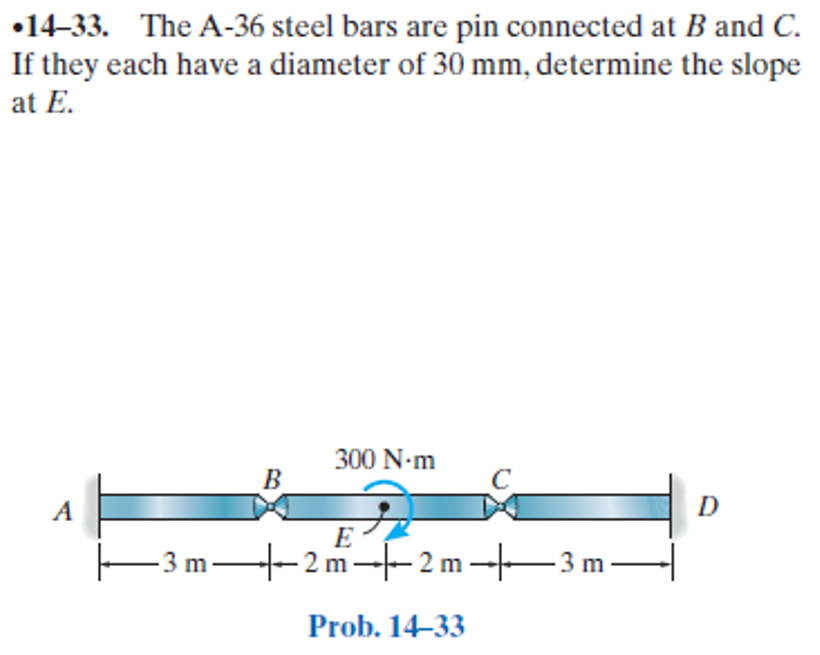

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-33P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-33P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'moment', 'Ma', 0);
b = b.add('hinge', 'force', 'Hb', 3*u.m);
b = b.add('concentrated', 'moment', -300*u.N*u.m, 5*u.m);
b = b.add('hinge', 'force', 'Hc', 7*u.m);
b = b.add('reaction', 'force', 'Rd', 10*u.m);
b = b.add('reaction', 'moment', 'Md', 10*u.m);
b.L = 10*u.m;

# section properties

D = 30*u.mm;
b.E = rewrite(200*u.GPa, [u.N u.m]);
b.I = rewrite(sympi*(D/2)^4/4, u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{2\,x^{2}\,\left(x-9\,m\right)}{405\,\pi }\,\frac{1}{m^{2}} & \text{ if }x\leq 3\,m\\ -\frac{2\,\left(x-5\,m\right)\,\left(x^{2}-4\,x\,m+30\,m^{2}\right)}{405\,\pi }\,\frac{1}{m^{2}} & \text{ if }x\in \left(3\,m,5\,m\right]\\ -\frac{2\,\left(x-5\,m\right)\,\left(x^{2}-16\,x\,m+90\,m^{2}\right)}{405\,\pi }\,\frac{1}{m^{2}} & \text{ if }x\in \left(5\,m,7\,m\right]\\ -\frac{2\,\left(x-1\,m\right)\,{\left(x-10\,m\right)}^{2}}{405\,\pi }\,\frac{1}{m^{2}} & \text{ if }7\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{2\,x\,\left(x-6\,m\right)}{135\,\pi }\,\frac{1}{m^{2}} & \text{ if }x\leq 3\,m\\ -\frac{2\,\left(3\,x^{2}-18\,x\,m+50\,m^{2}\right)}{405\,\pi }\,\frac{1}{m^{2}} & \text{ if }x\in \left(3\,m,5\,m\right]\\ -\frac{2\,\left(3\,x^{2}-42\,x\,m+170\,m^{2}\right)}{405\,\pi }\,\frac{1}{m^{2}} & \text{ if }x\in \left(5\,m,7\,m\right]\\ -\frac{2\,\left(x-4\,m\right)\,\left(x-10\,m\right)}{135\,\pi }\,\frac{1}{m^{2}} & \text{ if }7\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -75\,\left(x-3\,m\right)\,N & \text{ if }x\leq 5\,m\\ -75\,\left(x-7\,m\right)\,N & \text{ if }5\,m<x \end{array}\right.$$

v

$$v(x) = -75\,N$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ma} & -225\,N\,m\\ \mathrm{Md} & -225\,N\,m\\ \mathrm{Ra} & -75\,N\\ \mathrm{Rd} & 75\,N \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & 75\,N\\ \mathrm{Hc} & 75\,N \end{array}\right)$$

# shear and moment diagram

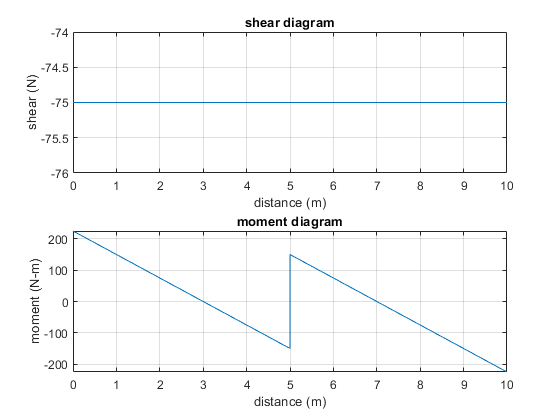

beam.shear_moment(m, v, [0 b.L], {'N' 'm'});

# slope at E

b.E = rewrite(b.E, u.GPa);
b.I = rewrite(b.I, u.mm);
dyE = rewrite(dy(5*u.m)*u.rad, u.deg);
dyE_vpa = vpa(dyE, 3) %#ok<NASGU> 

$$dyE\_vpa = -3.15\,\deg$$

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear dyE_vpa;